# sobal算子

说明：用Matlab的实时编辑器打开运行

## 1、设置算子

plateX=[-1 -2 -1;0 0 0;1 2 1];
plateY=[-1 0  1;-2 0 2;-1 0 1];

## 2、读取并显示原图

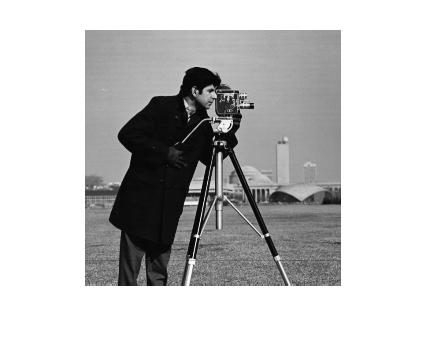

X=imread('cameraman.tif');
figure
imshow(X);

X=double(X);
[height,width]=size(X);     % 检索图像大小

## 3、计算dx即X方向

N=size(plateX,1);           % 检索模板大小
dX=X;                       % 保存计算后的图像（double类型）
for i=1:height-2
    for j=1:width-2
        % 模板卷积运算
        temp=plateX.*X(i:i+(N-1),j:j+(N-1)); % 模板与图像数据点乘
        temp=sum(sum(temp));                % 求和
        % 平方并写入图像
        dX(i:i+(N-1)/2,j:j+(N-1)/2)=temp.^2;
    end
end

## 4、计算dy即Y方向

N=size(plateY,1);           % 检索模板大小
dY=double(X);               % 保存计算后的图像（double类型）
for i=1:height-2
    for j=1:width-2
        % 模板卷积运算
        temp=plateY.*X(i:i+(N-1),j:j+(N-1)); % 模板与图像数据点乘
        temp=sum(sum(temp));                % 求和
        % 平方写入图像
        dY(i:i+(N-1)/2,j:j+(N-1)/2)=temp.^2;
    end
end

## 5、计算S得到sobal处理后的图像

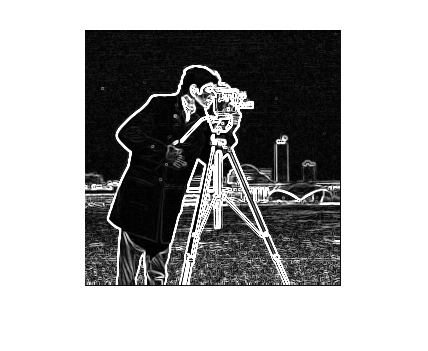

S=sqrt(dX+dY);
figure
imshow(uint8(S));

## 6、加上原图可得到轮廓

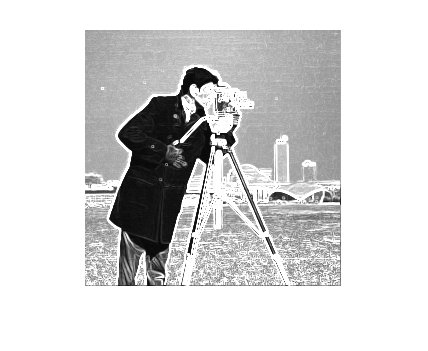

I=X+S;
figure
imshow(uint8(I));